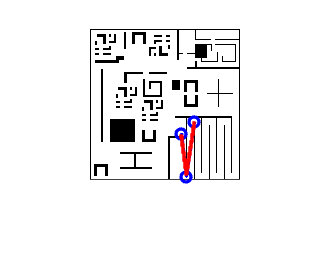

clear; clc; close all;
mapa2;
img = imread('mapa2.pgm');
origen = input('Nodo origen: ');
destino = input('Nodo destino: ');
[coste, ruta] = dijkstra(costes, origen, destino);
if isempty(ruta)
    disp('No se ha podido llegar al destino.');
    return;
end
coords = nodos(ruta, 2:3);
figure;
imshow(flipud(img)); hold on;
set(gca, 'YDir', 'normal');
plot(coords(:,1), coords(:,2), 'bo-', 'LineWidth', 2);
pos = coords(1,:);
llego = true;
for i = 2:size(coords,1)
    objetivo = coords(i,:);
    max_iter = 1000;
    iter = 0;
    while norm(pos - objetivo) > 3 && iter < max_iter
        iter = iter + 1;
        F_attr = fuerza_atractiva(pos, objetivo);
        F_rep  = fuerza_repulsiva(pos, img);
        F_attr = reshape(F_attr,1,2);
        F_rep  = reshape(F_rep,1,2);
        F_total = F_attr + F_rep;
        F_total = F_total / (norm(F_total) + 1e-6);
        pos = pos + 0.4 * F_total;
        plot(pos(1), pos(2), 'r.');
        drawnow limitrate;
    end
    if iter >= max_iter
        llego = false;
        break;
    end
end
if llego
    disp('El robot ha llegado al destino.');
else
    disp('No se ha podido llegar al destino.');
end